# Darknet YoLoV4 for LEDs Detection Project 

This respository uses simplified and minimal code to reproduce the yolov3 / yolov4 detection networks for LED detection Project.

The highlights are as follows:

- Reference Link: https://github.com/cuixing158/yolov3-yolov4-matlab

## 1、Load model

clear all;
cfg_file = 'cfg/yolov4-led.cfg';
weight_file = 'weights/yolov4-led.weights';
throushold = 0.5;
NMS = 0.4;


fid = fopen('obj.names','r');
names = textscan(fid, '%s', 'Delimiter',{'   '});
fclose(fid);
classesNames = categorical(names{1});
RGB = randi(255,length(classesNames),3);

## 2、Prediction

img = imread('example.jpg');
outFeatures = yolov3v4Predict(cfg_file,weight_file,img);

This module No: 1 [net]           ,have #params:0         ,FLops:0           ,feature map size:(416*416),channels in:-           ,channels out:3           
This module No: 2 [convolutional] ,have #params:1024      ,FLops:177209344   ,feature map size:(416*416),channels in:3           ,channels out:32          
This module No: 3 [convolutional] ,have #params:18752     ,FLops:811286528   ,feature map size:(208*208),channels in:32          ,channels out:64          
This module No: 4 [convolutional] ,have #params:4416      ,FLops:191053824   ,feature map size:(208*208),channels in:64          ,channels out:64          
This module No: 5 [route]         ,have #params:0         ,FLops:0           ,feature map size:(208*208),channels in:64          ,channels out:64          
This module No: 6 [convolutional] ,have #params:4416      ,FLops:191053824   ,feature map size:(208*208),channels in:64          ,channels out:64          
This module No: 7 [convolutional] ,have #params:2208      ,FLops

## 3. Show Results

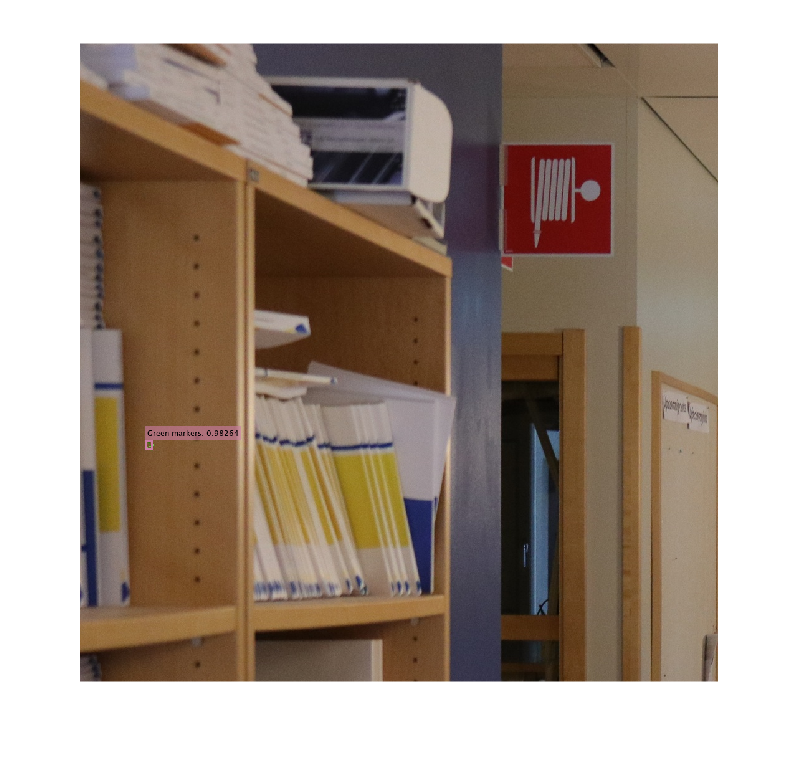

scores = outFeatures(:,5);
outFeatures = outFeatures(scores>throushold,:);

allBBoxes = outFeatures(:,1:4);
allScores = outFeatures(:,5);
[maxScores,indxs] = max(outFeatures(:,6:end),[],2);
allScores = allScores.*maxScores;
allLabels = classesNames(indxs);


if ~isempty(allBBoxes)
    [bboxes,scores,labels] = selectStrongestBboxMulticlass(allBBoxes,allScores,allLabels,...
        'RatioType','Min','OverlapThreshold',NMS);
    annotations = string(labels) + ": " + string(scores);
    [~,ids] = ismember(labels,classesNames);
    colors = RGB(ids,:);
    img = insertObjectAnnotation(img,...
        'rectangle',bboxes,cellstr(annotations),...
        'Color',colors,...
        'LineWidth',3);
    imshow(img);
end